# MINI-PROJECT 2: 

# ***TRAFFIC ENGINEERING OF TELECOMMUNICATION NETWORKS***

Pedro Caio

17/12/2024

clearvars; close all; clc;

load("InputDataProject2.mat", "L", "Links", "Nodes", "T");
nNodes= size(Nodes,1);
nLinks= size(Links,1);
nFlows= size(T,1);
nFlows_unicast = nnz(T(:,1) == 1 | T(:,1) == 2);
nFlows_unicast1 = nnz(T(:,1) == 1);

v = 2e5;
D = L/v; % propagation delay

## Task 1

In Task 1, consider the solutions where all traffic flows of both unicast services ($s = 1$ and  $s = 2$) are routed through the shortest propagation delay path. 

### **1.a.**

Compute the worst round-trip delay and the average round trip delay of each of the $3$ services (presenting all values in milliseconds) if the anycast nodes of the anycast service  ($s = 3$) are network nodes $3$ and $10$. 

**Answer:**

anycastNodes = [3, 10];
unicastservices = [1, 2];

[sP,nSP,totalCosts_unicast_a, totalCosts_anycast_a,T] = createPathFlows(D,T,1,unicastservices,anycastNodes);

totalCosts_unicast1_a = totalCosts_unicast_a(1:nFlows_unicast1);
totalCosts_unicast2_a = totalCosts_unicast_a(nFlows_unicast1:end);

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 3  10



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(totalCosts_unicast1_a*2)*1e3)

Worst round-trip delay (unicast service s=1) = 9.04 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(totalCosts_unicast1_a*2)*1e3)

Average round-trip delay (unicast service s=1) = 5.42 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(totalCosts_unicast2_a*2)*1e3)

Worst round-trip delay (unicast service s=2) = 11.07 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(totalCosts_unicast2_a*2)*1e3)

Average round-trip delay (unicast service s=2) = 5.89 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_a*2)*1e3)

Worst round-trip delay (anycast service) = 6.16 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_a*2)*1e3)

Average round-trip delay (anycast service) = 3.43 ms


### **1.b.**

Determine the link loads of all links and the worst link load of the network of the previous solution.

**Answer:**

sol= ones(1,nFlows);
Loads_b= calculateLinkLoads(nNodes,Links,T(:,2:end),sP,sol);
W_b = max(max(Loads_b(:,3:4)));

fprintf("Anycast nodes= %s\n", num2str(anycastNodes))

Anycast nodes= 3  10


fprintf("Worst link load = %.2f\n", W_b)

Worst link load = 98.20



for i=1:size(Loads_b,1)
    fprintf('{%2d - %2d}: %5.2f %5.2f \n', Loads_b(i,1), Loads_b(i,2), Loads_b(i,3), Loads_b(i,4))
end

{ 1 -  2}: 15.00 15.20 
{ 1 -  5}: 20.30 26.20 
{ 1 -  7}:  0.00  0.00 
{ 2 -  3}: 48.00 52.00 
{ 2 -  4}: 33.10 34.20 
{ 2 -  5}: 47.80 48.90 
{ 3 -  6}: 31.50  3.00 
{ 3 -  8}: 33.10 31.60 
{ 4 -  5}: 36.00 21.00 
{ 4 -  8}: 34.40 35.20 
{ 4 -  9}: 13.40 15.60 
{ 4 - 10}: 28.30 46.90 
{ 5 -  7}: 47.80 48.90 
{ 6 -  8}: 11.60  9.90 
{ 6 - 14}: 38.90 27.80 
{ 6 - 15}:  8.50  0.90 
{ 7 -  9}: 55.50 71.10 
{ 8 - 10}: 76.80 88.00 
{ 8 - 12}: 14.80 14.10 
{ 9 - 10}: 70.30 98.20 
{10 - 11}: 85.60 65.50 
{11 - 13}: 61.70 46.50 
{12 - 13}: 15.00 17.10 
{12 - 14}: 14.80 14.10 
{13 - 14}: 40.90 40.80 
{13 - 16}:  0.00  0.00 
{14 - 15}: 29.30 29.40 
{15 - 16}:  0.00  0.00 


### **1.c.**

Consider that you can freely select the anycast nodes of the anycast service. Try all possible combinations of 2 nodes and select the one that minimizes the worst link load. Indicate the two selected nodes, the worst round-trip delay and the average round trip delay of each service.

**Answer:**

n_anycastNodes = 2;

% Optimization loop
W_best = inf;
sol= ones(1,nFlows);
for anycastNodes = nchoosek(1:nNodes,n_anycastNodes)'
    [sP,nSP,totalCosts_unicast, totalCosts_anycast,T] = createPathFlows(D,T,1,unicastservices,anycastNodes);

    % minimizing the worst link load
    Loads= calculateLinkLoads(nNodes,Links,T(:,2:end),sP,sol);
    W_i = max(max(Loads(:,3:4)));

    if W_i < W_best
        anycastNodes_best_c = anycastNodes;
        W_best = W_i;
        T_best = T;
        totalCosts_unicast_best_c = totalCosts_unicast;
        totalCosts_anycast_best_c = totalCosts_anycast;
    end
end

totalCosts_unicast1_best_c = totalCosts_unicast_best_c(1:nFlows_unicast1);
totalCosts_unicast2_best_c = totalCosts_unicast_best_c(nFlows_unicast1:end);

fprintf("Anycast nodes= %s\n", num2str(anycastNodes_best_c'))

Anycast nodes= 1  6



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(totalCosts_unicast1_best_c*2)*1e3)

Worst round-trip delay (unicast service s=1) = 9.04 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(totalCosts_unicast1_best_c*2)*1e3)

Average round-trip delay (unicast service s=1) = 5.42 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(totalCosts_unicast2_best_c*2)*1e3)

Worst round-trip delay (unicast service s=2) = 11.07 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(totalCosts_unicast2_best_c*2)*1e3)

Average round-trip delay (unicast service s=2) = 5.89 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_best_c*2)*1e3)

Worst round-trip delay (anycast service) = 6.41 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_best_c*2)*1e3)

Average round-trip delay (anycast service) = 3.02 ms


### **1.d.**

Again, consider that you can freely select the anycast nodes of the anycast service. Try all possible combinations of 2 nodes and select the one that minimizes the worst round-trip delay of the anycast service. Indicate the two selected nodes, the worst round-trip delay and the average round trip delay of each service.

**Answer:**

% Optimization loop
W_best = inf;
for anycastNodes =  nchoosek(1:nNodes,n_anycastNodes)'
    [sP,nSP,totalCosts_unicast, totalCosts_anycast,T] = createPathFlows(D,T,1,unicastservices,anycastNodes);

    % minimizing the worst round-trip delay of the anycast service
    W_i = max(totalCosts_anycast*2);
    
    Loads= calculateLinkLoads(nNodes,Links,T(:,2:end),sP,sol);
    W_Load = max(max(Loads(:,3:4)));

    if W_i < W_best
        anycastNodes_best_d = anycastNodes;
        W_best = W_i;
        T_best = T;
        bestLoad = W_Load;
        totalCosts_unicast_best_d = totalCosts_unicast;
        totalCosts_anycast_best_d = totalCosts_anycast;
    end
end

Unrecognized function or variable 'n_anycastNodes'.


totalCosts_unicast1_best_d = totalCosts_unicast_best_d(1:nFlows_unicast1);
totalCosts_unicast2_best_d = totalCosts_unicast_best_d(nFlows_unicast1:end);

fprintf("Anycast nodes= %s\n", num2str(anycastNodes_best_d'))

fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(totalCosts_unicast1_best_d*2)*1e3)
fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(totalCosts_unicast1_best_d*2)*1e3)

fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(totalCosts_unicast2_best_d*2)*1e3)
fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(totalCosts_unicast2_best_d*2)*1e3)

fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_best_d*2)*1e3)
fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_best_d*2)*1e3)

fprintf("Link Load = %f", bestLoad);

### **1.e.**

Again, consider that you can freely select the anycast nodes of the anycast service. Try all possible combinations of 2 nodes and select the one that minimizes the average round trip delay of the anycast service. Indicate the two selected nodes, the worst round-trip delay and the average round trip delay of each service. 

**Answer:**

% Optimization loop
W_best = inf;
sol= ones(1,nFlows);
for anycastNodes =  nchoosek(1:nNodes,n_anycastNodes)'
    [sP,nSP,totalCosts_unicast, totalCosts_anycast,T] = createPathFlows(D,T,1,unicastservices,anycastNodes);

    % minimizing the average round-trip delay of the anycast service
    W_i = mean(totalCosts_anycast*2);

    if W_i < W_best
        anycastNodes_best_e = anycastNodes;
        W_best = W_i;
        T_best = T;
        totalCosts_unicast_best_e = totalCosts_unicast;
        totalCosts_anycast_best_e = totalCosts_anycast;
    end
end

totalCosts_unicast1_best_e = totalCosts_unicast_best_e(1:nFlows_unicast1);
totalCosts_unicast2_best_e = totalCosts_unicast_best_e(nFlows_unicast1:end);

fprintf("Anycast nodes= %s\n", num2str(anycastNodes_best_e'))

Anycast nodes= 5  14



fprintf("Worst round-trip delay (unicast service s=1) = %.2f ms\n", max(totalCosts_unicast1_best_e*2)*1e3)

Worst round-trip delay (unicast service s=1) = 9.04 ms


fprintf("Average round-trip delay (unicast service s=1) = %.2f ms\n", mean(totalCosts_unicast1_best_e*2)*1e3)

Average round-trip delay (unicast service s=1) = 5.42 ms



fprintf("Worst round-trip delay (unicast service s=2) = %.2f ms\n", max(totalCosts_unicast2_best_e*2)*1e3)

Worst round-trip delay (unicast service s=2) = 11.07 ms


fprintf("Average round-trip delay (unicast service s=2) = %.2f ms\n", mean(totalCosts_unicast2_best_e*2)*1e3)

Average round-trip delay (unicast service s=2) = 5.89 ms



fprintf("Worst round-trip delay (anycast service) = %.2f ms\n", max(totalCosts_anycast_best_e*2)*1e3)

Worst round-trip delay (anycast service) = 4.90 ms


fprintf("Average round-trip delay (anycast service) = %.2f ms\n", mean(totalCosts_anycast_best_e*2)*1e3)

Average round-trip delay (anycast service) = 2.52 ms


### **1.f.**

Compare the results obtained in all experiments of Task 1 and draw all possible conclusions. 

**Answer:**

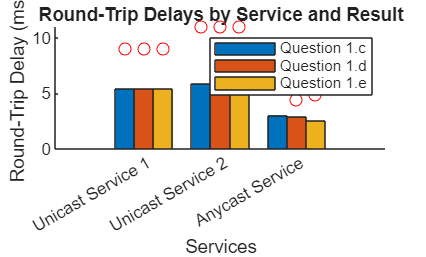

% Calculate means and max values
c_means = [mean(totalCosts_unicast1_best_c), mean(totalCosts_unicast2_best_c), mean(totalCosts_anycast_best_c)] * 2 * 1e3;
d_means = [mean(totalCosts_unicast1_best_d), mean(totalCosts_unicast2_best_d), mean(totalCosts_anycast_best_d)] * 2 * 1e3;
e_means = [mean(totalCosts_unicast1_best_e), mean(totalCosts_unicast2_best_e), mean(totalCosts_anycast_best_e)] * 2 * 1e3;

c_max = [max(totalCosts_unicast1_best_c), max(totalCosts_unicast2_best_c), max(totalCosts_anycast_best_c)] * 2 * 1e3;
d_max = [max(totalCosts_unicast1_best_d), max(totalCosts_unicast2_best_d), max(totalCosts_anycast_best_d)] * 2 * 1e3;
e_max = [max(totalCosts_unicast1_best_e), max(totalCosts_unicast2_best_e), max(totalCosts_anycast_best_e)] * 2 * 1e3;

% Labels for the x-axis
labels = {'Unicast Service 1', 'Unicast Service 2', 'Anycast Service'};

% Bar plot with means
x = 1:length(labels);  % the label locations
width = 0.25;  % the width of the bars

fcomparison_1f = figure;
hold on;
bar(x - width, c_means, width, 'DisplayName', 'Question 1.c');
bar(x, d_means, width, 'DisplayName', 'Question 1.d');
bar(x + width, e_means, width, 'DisplayName', 'Question 1.e');

% Adding points for the max values
plot(x - width, c_max, 'ro', 'HandleVisibility', 'off');
plot(x, d_max, 'ro', 'HandleVisibility', 'off');
plot(x + width, e_max, 'ro', 'HandleVisibility', 'off');

% Add some text for labels, title and custom x-axis tick labels, etc.
xlabel('Services');
ylabel('Round-Trip Delay (ms)');
title('Round-Trip Delays by Service and Result');
set(gca, 'XTick', x, 'XTickLabel', labels);
legend('show');
hold off;

% saveas(fcomparison_1f, fullfile('doc/assets', '1f_comparison.png')) % does not work
saveas(fcomparison_1f, fullfile('doc/assets', '1f_comparison.svg'))

...

## References:

None

## Internal Functions:

function [sP,nSP,totalCosts_unicast, totalCosts_anycast,T] = createPathFlows(costMatrix,T,k,unicastservices,anycastNodes)
%CREATEPATHFLOWS Computes the shortest paths and their costs for unicast and anycast services.
%   [sP, nSP, totalCosts_unicast, totalCosts_anycast, T] = createPathFlows(D, T, k, unicastservices, anycastNodes)
%   computes the shortest paths for all traffic flows in the network, 
%   considering both unicast and anycast services. The function returns the
%   paths, the number of shortest paths, and the total costs for unicast 
%   and anycast services.
%
%   Inputs:
%       costMatrix - Matrix used to determine the shortest path between 
%           nodes (NxN matrix). This can represent weights, delays, or any 
%           other metric.
%       T - Matrix of traffic flows (nFlowsx5 matrix), with:
%           - Column 1: Service type (e.g. 1 for unicast service 1, 2 for unicast service 2, 3 for anycast service).
%           - Column 2: Source node of the traffic flow.
%           - Column 3: Destination node of the traffic flow (0 for anycast flows).
%           - Column 4: Throughput from source to destination (in Gbps).
%           - Column 5: Throughput from destination to source (in Gbps).
%       k - Number of shortest paths to compute (1 for the shortest path).
%       unicastservices - Vector of unicast service types (e.g., [1, 2]).
%       anycastNodes - Vector of nodes that can serve as anycast destinations (e.g., [3, 10]).
%
%   Outputs:
%       sP - Cell array of shortest paths for each traffic flow.
%       nSP - Vector of the number of shortest paths for each traffic flow.
%       totalCosts_unicast - Vector of total costs (based on D metric) for unicast flows.
%       totalCosts_anycast - Vector of total costs (based on D metric) for anycast flows.
%       T - Updated traffic flow matrix with destination nodes for anycast flows.
%
%   Example:
%       anycastNodes = [3, 10];
%       unicastservices = [1, 2];
%       [sP, nSP, totalCosts_unicast, totalCosts_anycast, T] = createPathFlows(D, T, 1, unicastservices, anycastNodes);
%
%   This function uses the kShortestPath function to compute the shortest paths and their costs.
    nFlows= size(T,1);
    nFlows_unicast = nnz(ismember(T(:,1),unicastservices));
    n_anycastNodes = length(anycastNodes);
    totalCosts_unicast = zeros(nFlows_unicast, 1);
    totalCosts_anycast = zeros(nFlows - nFlows_unicast, 1);
    
    % Possible anycast paths
    possible_shortestPath = cell(n_anycastNodes,1);
    possible_totalCost = zeros(n_anycastNodes,1);
    
    k= 1;
    sP= cell(1,nFlows);
    nSP= zeros(1,nFlows);

    for f = 1:nFlows
        if ismember(T(f,1), unicastservices)
            % Flow is unicast
            [shortestPath, totalCost] = kShortestPath(costMatrix,T(f,2),T(f,3),k);
            sP{f}= shortestPath;
            nSP(f)= length(totalCost);
            totalCosts_unicast(f) = totalCost;
        else 
            % Flow is anycast
            if ismember(T(f,2), anycastNodes)
                sP{f} = {T(f,2)};
                nSP(f) = 1;
                T(f,3) = T(f,2);
                % totalCost is already initialize to zero
            else
                for node = 1:n_anycastNodes
                    [possible_shortestPath(node), possible_totalCost(node)] = kShortestPath(costMatrix,T(f,2),anycastNodes(node),k);
                end
                [M, I] = min(possible_totalCost);
                sP{f} = possible_shortestPath(I);
                nSP(f) = length(possible_totalCost(I));
                % index of array must begin in 1
                totalCosts_anycast(f - nFlows_unicast) = possible_totalCost(I);
                T(f,3) = anycastNodes(I);
            end
        end
    end
end